## Q3. (a)

Given system,

%Create VCM Plant Model
%Note:  This model is from "Design and testing of track-following
%controllers for dual-state servo systems with PZT actuated suspensions" by
%Li and Horowitz, Microsystem Technologies, 2002
Gv = 10;  %DC Gain
Gv1 = tf((2*pi*135)^2,[1 2*0.1*2*pi*135 (2*pi*135)^2]);
Gv2 = tf((2*pi*5500)^2,[1 2*0.03*2*pi*5500 (2*pi*5500)^2]);
Gv3 = tf((2*pi*8640)^2,[1 2*0.05*2*pi*8640 (2*pi*8640)^2]);
Gv4 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
VCM = Gv*Gv1*Gv2*Gv3*Gv4;

Gp = 0.1;  %DC gain
Gp1 = tf((2*pi*8460)^2,[1 2*0.01*2*pi*8460 (2*pi*8460)^2]);
Gp2 = 5500^2/5650^2*tf([1 2*.03*2*pi*5650 (2*pi*5650)^2],[1 2*.03*2*pi*5500 (2*pi*5500)^2]);
Gp3 = 7300^2/7650^2*tf([1 2*.015*2*pi*7650 (2*pi*7650)^2],[1 2*.03*2*pi*7300 (2*pi*7300)^2]);
Gp4 = 8070^2/8250^2*tf([1 2*.02*2*pi*8250 (2*pi*8250)^2],[1 2*.015*2*pi*8070 (2*pi*8070)^2]);
Gp5 = 10650^2/10530^2*tf([1 2*.015*2*pi*10530 (2*pi*10530)^2],[1 2*.01*2*pi*10650 (2*pi*10650)^2]);
PZT = Gp*Gp1*Gp2*Gp3*Gp4*Gp5;

Create a DISO model

G = [VCM,PZT]

G =
 
  From input 1 to output:
                                                                   
                               2.306e25 s^2 + 3.325e28 s + 5.327e34
                                                                   
  -----------------------------------------------------------------------------------------------
                                                                                                 
  s^8 + 1.042e04 s^7 + 6.279e09 s^6 + 4.088e13 s^5 + 1.23e19 s^4 + 3.829e22 s^3 + 7.419e27 s^2   
                                                                                                 
                                                                          + 1.282e30 s + 5.327e33
                                                                                                 
 
  From input 2 to output:
                                                                                                 
  2.386e08 s^8 + 1.821e12 s^7 + 2.543e18 s^6 + 1.4

Bode plot of the diso model

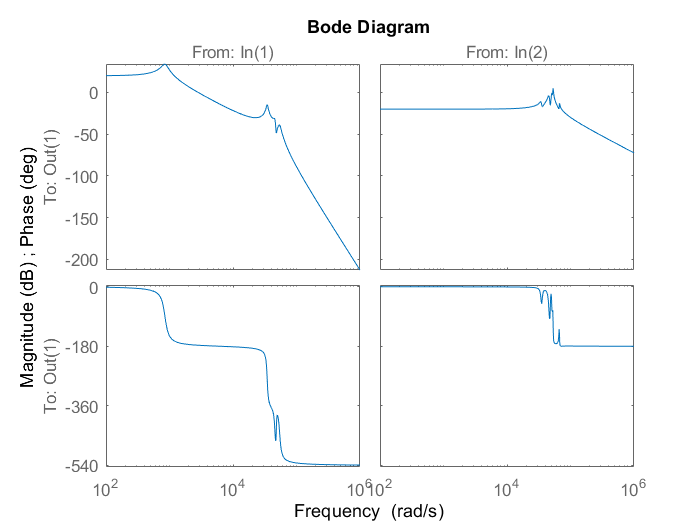

bode(G)

## Q3. (b)

Initialize transfer function and the weight parameters as done in Q2 (a), (c)

s = tf('s');
Wu_V = 1/100;
Wu_P = 1/10;
Wu = [Wu_V 0;0 Wu_P];
GAM = 10;  
BW = 3000*2*pi; 
BW_step = 25;
M = 10^(6/20);
A = 1000;

Optimization loop

while GAM>1
    Wp = (s/sqrt(M)+BW)^2/(s+BW/sqrt(A))^2;
    Wt = makeweight(0.5,5*BW,1000);
    [K,CL,GAM,info] = mixsyn(G,Wp,Wu,Wt); 
    BW = BW - BW_step; 
end

Gamma Value

GAM

GAM = 0.9985

Semsitivity function

S = inv(eye(1)-G*K);

Somplementary sensitivity function

T = 1-S;

Bode plot of sensitivity funciton

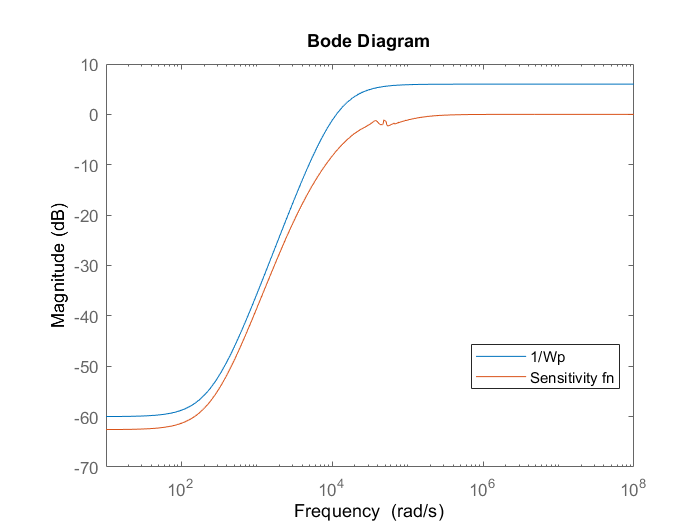

bodemag(1/Wp,S)
legend('1/Wp','Sensitivity fn',"Location",'best')

Bode plot of complementary sensitivity funciton

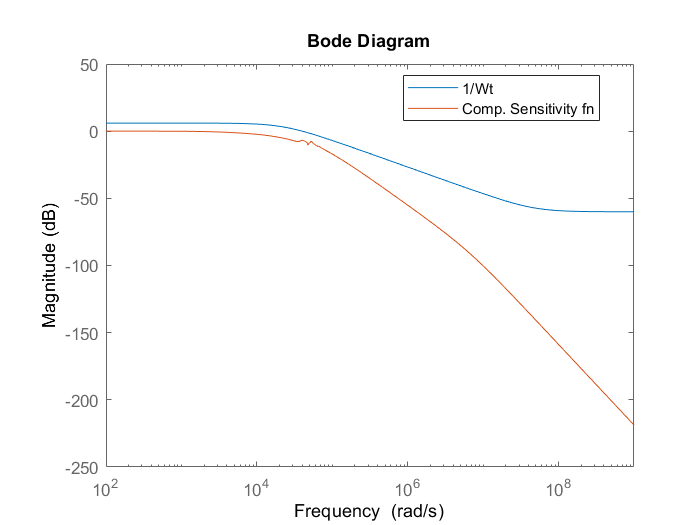

bodemag(1/Wt,T)
legend('1/Wt','Comp. Sensitivity fn',"Location",'best')

Bode magnitude plot of Wu*K*S

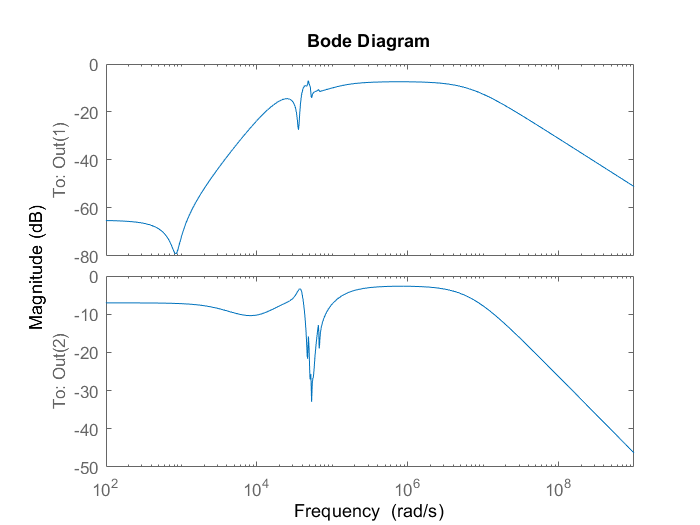

bodemag(Wu*K*S)